clear all
clc

% Parameters 
r1 = 1.5; r2 = 1.0;     % grow rate
b1 = 1.0; b2 = 1.0;     % saturation rate
c1 = 1.0; c2 = 0.5; c3 = 1.0; c4 = 1.0;     % competivity rate
rho = 0.01; alpha = 0.3;
s = 0.33;    % immune constant supply
d1 = 0.2;  % mortality rate for immune cells
gamma1 = 0.7; gamma2 = 1; gamma3 = 0.3;
k = 0.5;   %elimination rate

x_eq = [1; 0; 1.65; 0];
x_0 = [0.8; 0.5; 1; 0];
e_init = [x_eq - x_0 ; 0];
tspan = [0, 100];  

## LINEAR CONTROL : LQR

% Linearized system
J = [
    r2 * (1 - 2 * b2 * x_eq(1)) - c4 * x_eq(2) ,  -c4 * x_eq(1),   0, -gamma1 ;
    -c3 * x_eq(2),   r1 * (1 - 2 * b1 * x_eq(2)) - c2 * x_eq(3) - c3 * x_eq(1) ,  -c2 * x_eq(2), -gamma2 ;
    0,   (rho * alpha * x_eq(3)) / ((alpha + x_eq(2))^2) - c1 * x_eq(3),   (rho * x_eq(2)) / (alpha + x_eq(2)) - c1 * x_eq(2) - d1 - gamma2 , -gamma3 ;
    0, 0, 0, -k
];

B=[0; 0; 0; 1];
C=[0,1,0,0];
D=0;

% controllability
ctr = ctrb(J,B);
disp('Rank of Controllability matrix:');

Rank of Controllability matrix:


disp(rank(ctr));

     4



% sistema aumentato con integratore
A_int = [J  zeros(4,1)
         -C 0];
B_int = [B; -D];
C_int = [C, 0];
D_int = D;
x_0_int = [x_0;0];

% pesi LQR
Qi = 50;      %peso azione integrale
Qy = [50 0 0 0 ;
    0 10 0 0;
    0 0 50 0
    0 0 0 1];      % peso stati
Q = [Qy zeros(4,1);
    zeros(1,4) Qi];
R=5;

[K_LQR_int, ~, Poles_LQR_int] = lqr(A_int, B_int, Q, R);

K_LQ_p = K_LQR_int(:,1:4)

K_LQ_p =     0.0258   -5.0977    0.3238    2.7272


K_LQ_i = K_LQR_int(:,5)

K_LQ_i = 3.1623

% closed loop stability
A_cl = A_int - B_int * K_LQR_int;
eigenvalues = eig(A_cl);
disp('Eigenvalues of the closed loop system:');

Eigenvalues of the closed loop system:


disp(eigenvalues);

  -1.1884 + 1.4746i
  -1.1884 - 1.4746i
  -1.7750 + 0.0000i
  -0.5897 + 0.0000i
  -1.0108 + 0.0000i



if all(real(eigenvalues) < 0)
    disp('The system is stable under LQR control');
else
    disp('The system is not stable under LQR control');
end

The system is stable under LQR control


% data analysis LINEAR
time = out.L_normal.Time; 
data = out.L_normal.Data;  
y_final = data(end);  
peak_value = max(data);  
overshoot = (peak_value - y_final) / y_final * 100;  
tolerance = 0.05 * y_final;
time2 = out.L_tumor.Time; 
data2 = out.L_tumor.Data;  
y_final2 = data2(end);  
peak_value2 = max(data2);  
overshoot2 = (peak_value2 - 0.1) / 0.1 * 100;  
tolerance2 = 0.05 * y_final2;
% fprintf('L_tumor overshoot: %.2f%%\n', overshoot2);
time3 = out.L_immune.Time; 
data3 = out.L_immune.Data;  
y_final3 = data3(end);  
peak_value3 = max(data3);  
overshoot3 = (peak_value3 - y_final3) / y_final3 * 100;  
tolerance3 = 0.05 * y_final3;
fprintf('L_normal overshoot: %.2f%%\n', overshoot);

L_normal overshoot: 6.59%


fprintf('L_immune overshoot: %.2f%%\n', overshoot3);

L_immune overshoot: 6.31%


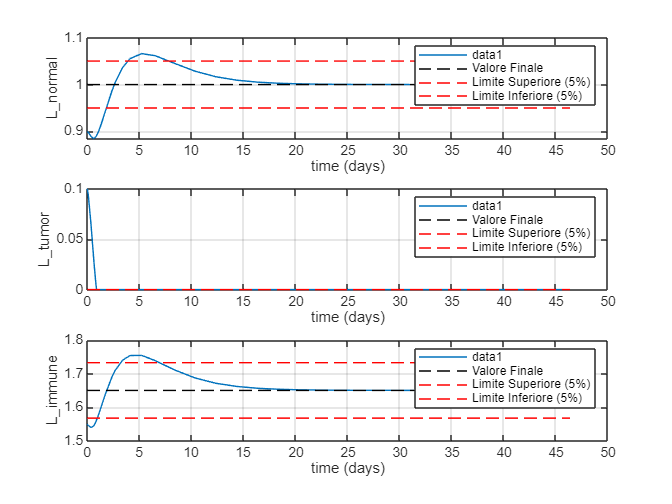


figure;
subplot(3,1,1) 
plot(time(1:50), data(1:50));
hold on;
plot(time(1:50), y_final * ones(size(time(1:50))), 'k--', 'DisplayName', 'Valore Finale');
plot(time(1:50), y_final + tolerance * ones(size(time(1:50))), 'r--', 'DisplayName', 'Limite Superiore (5%)');
plot(time(1:50), y_final - tolerance * ones(size(time(1:50))), 'r--', 'DisplayName', 'Limite Inferiore (5%)');
xlabel('time (days)');
ylabel('L\_normal');
legend;
grid on;
subplot(3,1,2) 
plot(time2(1:50), data2(1:50));
hold on;
plot(time2(1:50), y_final2 * ones(size(time2(1:50))), 'k--', 'DisplayName', 'Valore Finale');
plot(time2(1:50), y_final2 + tolerance2 * ones(size(time2(1:50))), 'r--', 'DisplayName', 'Limite Superiore (5%)');
plot(time2(1:50), y_final2 - tolerance2 * ones(size(time2(1:50))), 'r--', 'DisplayName', 'Limite Inferiore (5%)');
xlabel('time (days)');
ylabel('L\_tumor');
legend;
grid on;
subplot(3,1,3) 
plot(time3(1:50), data3(1:50));
hold on;
plot(time3(1:50), y_final3 * ones(size(time3(1:50))), 'k--', 'DisplayName', 'Valore Finale');
plot(time3(1:50), y_final3 + tolerance3 * ones(size(time3(1:50))), 'r--', 'DisplayName', 'Limite Superiore (5%)');
plot(time3(1:50), y_final3 - tolerance3 * ones(size(time3(1:50))), 'r--', 'DisplayName', 'Limite Inferiore (5%)');
xlabel('time (days)');
ylabel('L\_immune');
legend;
grid on;

% data analysis NONLINEAR
LQR_normal_time = out.LQR_normal.Time; 
LQR_normal_data = out.LQR_normal.Data;  
y_final = LQR_normal_data(end);  
peak_value = max(LQR_normal_data);  
overshoot = (peak_value - y_final) / y_final * 100;  
tolerance = 0.05 * y_final;

LQR_tumor_time = out.LQR_tumor.Time; 
LQR_tumor_data = out.LQR_tumor.Data;  
y_final2 = LQR_tumor_data(end);  
peak_value2 = max(LQR_tumor_data);  
overshoot2 = (peak_value2 - 0.1) / 0.1 * 100;  
tolerance2 = 0.05 * y_final2;

LQR_immune_time = out.LQR_immune.Time; 
LQR_immune_data = out.LQR_immune.Data;  
y_final3 = LQR_immune_data(end);  
peak_value3 = max(LQR_immune_data);  
overshoot3 = (peak_value3 - y_final3) / y_final3 * 100;  
tolerance3 = 0.05 * y_final3;
fprintf('NL_normal overshoot: %.2f%%\n', overshoot);

NL_normal overshoot: 0.00%


fprintf('NL_immune overshoot: %.2f%%\n', overshoot3);

NL_immune overshoot: 0.00%


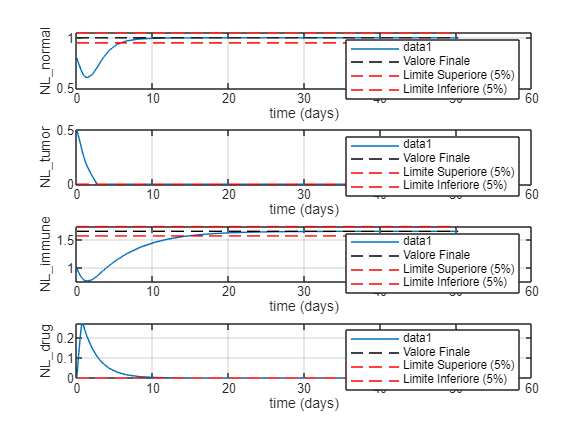


LQR_drug_time = out.LQR_drug.Time;
LQR_drug_data = out.LQR_drug.Data;
y_final4 = LQR_drug_data(end);  
tolerance4 = 0.05 * y_final4;

LQR_control_time = out.LQR_control.Time;
LQR_control_data = out.LQR_control.Data;

LQR_error_time = out.LQR_error.Time;
LQR_error_data = out.LQR_error.Data;

figure;
subplot(4,1,1) 
plot(LQR_normal_time(1:50), LQR_normal_data(1:50));
hold on;
plot(LQR_normal_time(1:50), y_final * ones(size(LQR_normal_time(1:50))), 'k--', 'DisplayName', 'Valore Finale');
plot(LQR_normal_time(1:50), y_final + tolerance * ones(size(LQR_normal_time(1:50))), 'r--', 'DisplayName', 'Limite Superiore (5%)');
plot(LQR_normal_time(1:50), y_final - tolerance * ones(size(LQR_normal_time(1:50))), 'r--', 'DisplayName', 'Limite Inferiore (5%)');
xlabel('time (days)');
ylabel('NL\_normal');
legend;
grid on;
subplot(4,1,2) 
plot(LQR_tumor_time(1:50), LQR_tumor_data(1:50));
hold on;
plot(LQR_tumor_time(1:50), y_final2 * ones(size(LQR_tumor_time(1:50))), 'k--', 'DisplayName', 'Valore Finale');
plot(LQR_tumor_time(1:50), y_final2 + tolerance2 * ones(size(LQR_tumor_time(1:50))), 'r--', 'DisplayName', 'Limite Superiore (5%)');
plot(LQR_tumor_time(1:50), y_final2 - tolerance2 * ones(size(LQR_tumor_time(1:50))), 'r--', 'DisplayName', 'Limite Inferiore (5%)');
xlabel('time (days)');
ylabel('NL\_tumor');
legend;
grid on;
subplot(4,1,3) 
plot(LQR_immune_time(1:50), LQR_immune_data(1:50));
hold on;
plot(LQR_immune_time(1:50), y_final3 * ones(size(LQR_immune_time(1:50))), 'k--', 'DisplayName', 'Valore Finale');
plot(LQR_immune_time(1:50), y_final3 + tolerance3 * ones(size(LQR_immune_time(1:50))), 'r--', 'DisplayName', 'Limite Superiore (5%)');
plot(LQR_immune_time(1:50), y_final3 - tolerance3 * ones(size(LQR_immune_time(1:50))), 'r--', 'DisplayName', 'Limite Inferiore (5%)');
xlabel('time (days)');
ylabel('NL\_immune');
legend;
grid on;
subplot(4,1,4) 
plot(LQR_drug_time(1:50), LQR_drug_data(1:50));
hold on;
plot(LQR_drug_time(1:50), y_final4 * ones(size(LQR_drug_time(1:50))), 'k--', 'DisplayName', 'Valore Finale');
plot(LQR_drug_time(1:50), y_final4 + tolerance4 * ones(size(LQR_drug_time(1:50))), 'r--', 'DisplayName', 'Limite Superiore (5%)');
plot(LQR_drug_time(1:50), y_final4 - tolerance4 * ones(size(LQR_drug_time(1:50))), 'r--', 'DisplayName', 'Limite Inferiore (5%)');
xlabel('time (days)');
ylabel('NL\_drug');
legend;
grid on;

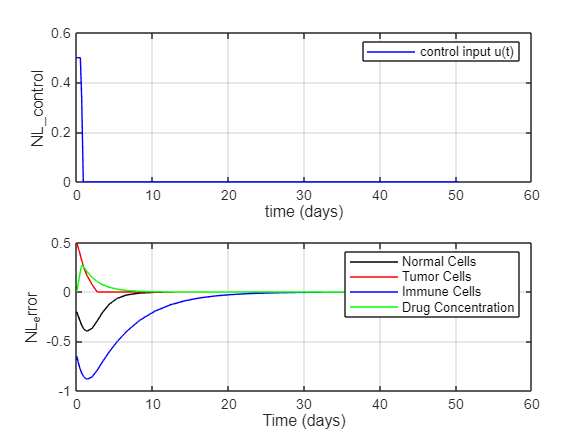

figure;
subplot(2,1,1) 
plot(LQR_control_time(1:50), LQR_control_data(1:50), 'b ', 'DisplayName','control input u(t)');
xlabel('time (days)');
ylabel('NL\_control');
legend;
grid on;
subplot(2,1,2)
plot(LQR_error_time(1:50), LQR_error_data(1:50,1), 'k', 'DisplayName', 'Normal Cells');
hold on;  
plot(LQR_error_time(1:50), LQR_error_data(1:50,2), 'r', 'DisplayName', 'Tumor Cells');
plot(LQR_error_time(1:50), LQR_error_data(1:50,3), 'b', 'DisplayName', 'Immune Cells');
plot(LQR_error_time(1:50), LQR_error_data(1:50,4), 'g', 'DisplayName', 'Drug Concentration');
xlabel('Time (days)');
ylabel('NL_error');
legend;
grid on;

## NONLINEAR CONTROL : SLIDING MODE

p1= 1;
p2= 1;
p3= 2;
p4= 15;

K= 20;
%K = 70;

%epsilon = 1e-3;
%epsilon = 1e-2;
epsilon = 1e-1;

% data analysis SMC
SMC_normal_time = out.SMC_normal.Time;
SMC_normal_data = out.SMC_normal.Data;  
y_final = SMC_normal_data(end);  
peak_value = max(SMC_normal_data);  
overshoot = (peak_value - y_final) / y_final * 100;  
tolerance = 0.05 * y_final;
SMC_tumor_time = out.SMC_tumor.Time; 
SMC_tumor_data = out.SMC_tumor.Data;  
y_final2 = SMC_tumor_data(end);  
peak_value2 = max(SMC_tumor_data);  
overshoot2 = (peak_value2 - 0.1) / 0.1 * 100;  
tolerance2 = 0.05 * y_final2;
SMC_immune_time = out.SMC_immune.Time; 
SMC_immune_data = out.SMC_immune.Data;  
y_final3 = SMC_immune_data(end);  
peak_value3 = max(SMC_immune_data);  
overshoot3 = (peak_value3 - y_final3) / y_final3 * 100;  
tolerance3 = 0.05 * y_final3;
fprintf('NL_normal overshoot: %.2f%%\n', overshoot);

NL_normal overshoot: 0.00%


fprintf('NL_immune overshoot: %.2f%%\n', overshoot3);

NL_immune overshoot: 0.00%


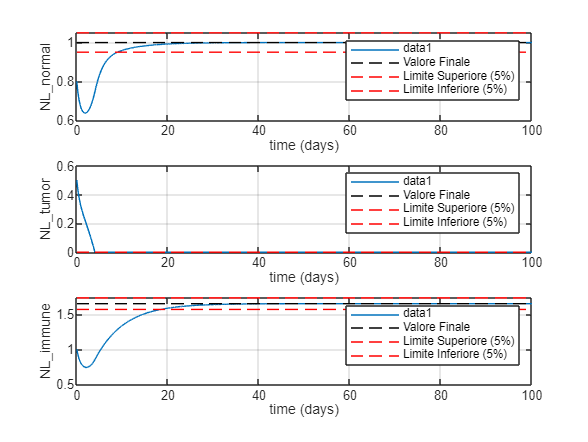


SMC_drug_time = out.SMC_drug.Time;
SMC_drug_data = out.SMC_drug.Data;  

figure;
subplot(3,1,1); 
plot(SMC_normal_time, SMC_normal_data);
hold on;
plot(SMC_normal_time, y_final * ones(size(SMC_normal_time)), 'k--', 'DisplayName', 'Valore Finale');
plot(SMC_normal_time, y_final + tolerance * ones(size(SMC_normal_time)), 'r--', 'DisplayName', 'Limite Superiore (5%)');
plot(SMC_normal_time, y_final - tolerance * ones(size(SMC_normal_time)), 'r--', 'DisplayName', 'Limite Inferiore (5%)');
xlabel('time (days)');
ylabel('NL\_normal');
legend;
grid on;
subplot(3,1,2); 
plot(SMC_tumor_time, SMC_tumor_data);
hold on;
plot(SMC_tumor_time, y_final2 * ones(size(SMC_tumor_time)), 'k--', 'DisplayName', 'Valore Finale');
plot(SMC_tumor_time, y_final2 + tolerance2 * ones(size(SMC_tumor_time)), 'r--', 'DisplayName', 'Limite Superiore (5%)');
plot(SMC_tumor_time, y_final2 - tolerance2 * ones(size(SMC_tumor_time)), 'r--', 'DisplayName', 'Limite Inferiore (5%)');
xlabel('time (days)');
ylabel('NL\_tumor');
legend;
grid on;
subplot(3,1,3); 
plot(SMC_immune_time, SMC_immune_data);
hold on;
plot(SMC_immune_time, y_final3 * ones(size(SMC_immune_time)), 'k--', 'DisplayName', 'Valore Finale');
plot(SMC_immune_time, y_final3 + tolerance3 * ones(size(SMC_immune_time)), 'r--', 'DisplayName', 'Limite Superiore (5%)');
plot(SMC_immune_time, y_final3 - tolerance3 * ones(size(SMC_immune_time)), 'r--', 'DisplayName', 'Limite Inferiore (5%)');
xlabel('time (days)');
ylabel('NL\_immune');
legend;
grid on;

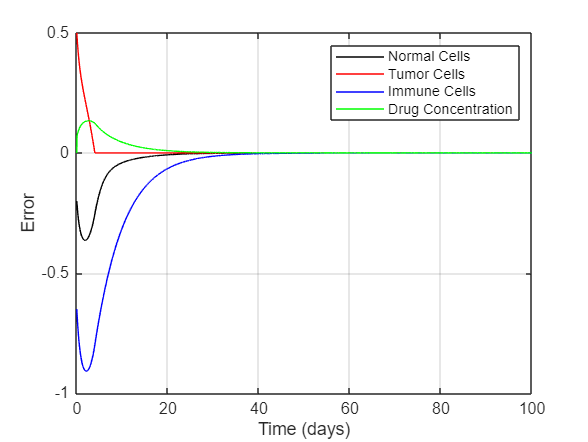


SMC_error_time = out.SMC_error.Time;
SMC_error_data = out.SMC_error.Data;

figure;
plot(SMC_error_time, SMC_error_data(:,1), 'k', 'DisplayName', 'Normal Cells');
hold on;  
plot(SMC_error_time, SMC_error_data(:,2), 'r', 'DisplayName', 'Tumor Cells');
plot(SMC_error_time, SMC_error_data(:,3), 'b', 'DisplayName', 'Immune Cells');
plot(SMC_error_time, SMC_error_data(:,4), 'g', 'DisplayName', 'Drug Concentration');
xlabel('Time (days)');
ylabel('Error');
legend;
grid on;

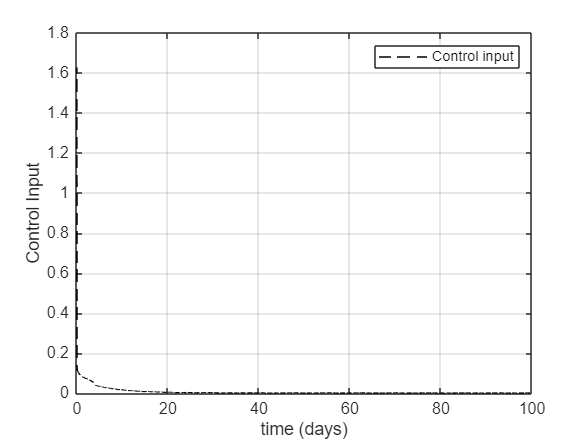


SMC_control_time = out.SMC_control.Time;
SMC_control_data = out.SMC_control.Data;

figure; 
plot(SMC_control_time , SMC_control_data,'k--','DisplayName', 'Control input');
xlabel('time (days)');
ylabel('Control Input');
legend;
grid on;

## NONLINEAR CONTROL: MPC

p = [r1, r2, b1, b2, c1, c2, c3, c4, rho, alpha, s, d1, gamma1, gamma2, gamma3, k];

Np = 6;                     % Orizzonte di predizione : 6 ore
Q = diag([10, 150, 10, 1]); % Matrice di Peso per lo Stato
R = 0.1;                    % Matrice di Peso per il Controllo

Tsim = 30;  % 30 giorni
Ts = 1/24;       % 1 ora

% Vincoli su Stato e Ingresso
u_min = 0;
u_max = 0.5;
x_max = [10; 10; 10; 10];
x_min = [0.3; 0; 0.3; 0];

u_zero = 0;
x = x_0;
x0_new = x_0;

X_hist = x';
U_hist = [];
cost_values = [];

% senza disutrbo
for t = 0:Ts:Tsim
    
    Np=min(Np,Tsim-t);
    objective = @(u) objective_fun(u, x0_new, x_eq, Q, R, p, Np, Ts);
    state_const = @(u) state_constraints(u, x0_new, p, x_max, x_min);

    options = optimoptions('fmincon','Algorithm','interior-point','MaxFunctionEvaluations',100,'MaxIterations',100);
    [u, fval, exitflag] = fmincon(objective, u_zero,[],[],[],[], u_min, u_max, state_const, options);
    
    cost_values = [cost_values; fval];  
    u_zero = u(1);

    [t, x] = ode45(@(t, x) tumor_growth_controlled(t, x, u_zero, p), [0 Ts], x0_new);

    if x(end, 2) < 0
        x (end, 2) = 0;
    end
    
    x0_new = x(end, :);  % lo stato attuale sarà il prossimo stato iniziale
        
    X_hist = [X_hist; x0_new];
    U_hist = [U_hist; u_zero];
end


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Initial point is a local minimum that satisfies the constraints.

Optimization completed because at the

x_eq_matrix = repmat(x_eq', Tsim/Ts+2, 1);
error = - x_eq_matrix + X_hist;
t_mpc = (0:Ts:Tsim); 

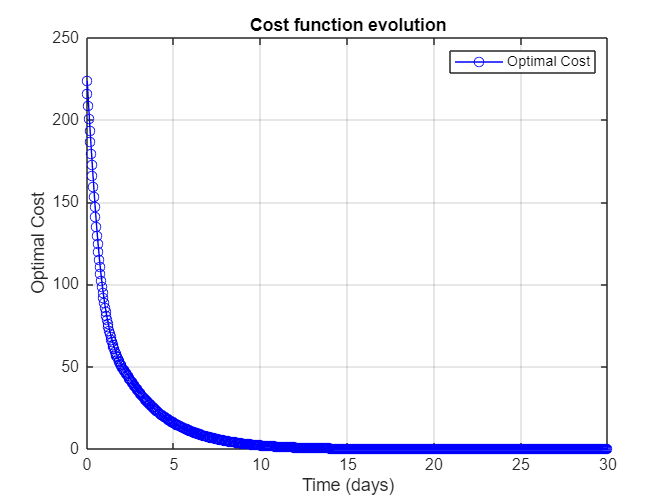

figure;
plot(t_mpc, cost_values, 'b-o');
xlabel('Time (days)');
ylabel('Optimal Cost');
title('Cost function evolution');
grid on;
legend('Optimal Cost');

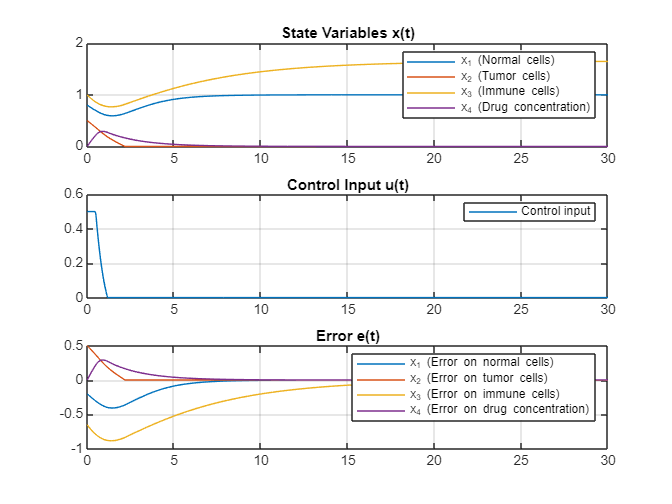


figure;
subplot(3,1,1);
plot(t_mpc',X_hist(1:721,:));
legend('x_1 (Normal cells)', 'x_2 (Tumor cells)', 'x_3 (Immune cells)', 'x_4 (Drug concentration)');
title('State Variables x(t)');
grid on;
subplot(3,1,2);
plot(t_mpc',U_hist);
legend('Control input')
title('Control Input u(t)');
grid on;
subplot(3,1,3);
plot(t_mpc',error(1:721,:));
title('Error e(t)');
legend('x_1 (Error on normal cells)', 'x_2 (Error on tumor cells)', 'x_3 (Error on immune cells)', 'x_4 (Error on drug concentration)');
grid on;

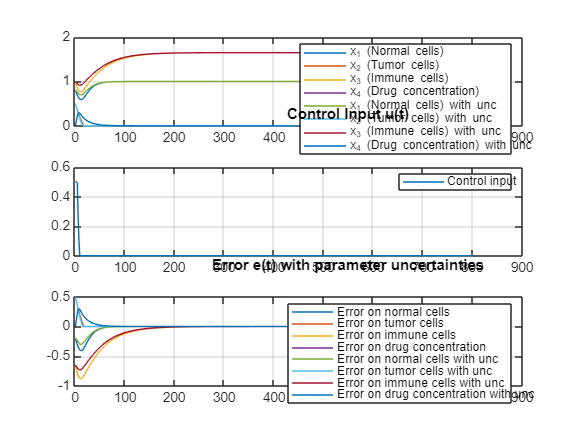

%% PARAMETERS UNCERTAINTIES
c1_real = c1 * (1 - 0.5);
c4_real = c4 * (1 - 0.5);
p_real = [r1, r2, b1, b2, c1_real, c2, c3, c4_real, rho, alpha, s, d1, gamma1, gamma2, gamma3, k];
X_real = x_0';
x0_real = x_0;
for i = 1:length(U_hist)
    u_real = U_hist(i);  
    [t_real, x_real] = ode45(@(t, x) tumor_growth_controlled(t, x, u_real, p_real), [0 Ts], x0_real);
    x_real(end, 2) = max(x_real(end, 2), 0);
    x0_real = x_real(end, :);
    X_real = [X_real; x0_real];
end
error_real = - x_eq_matrix + X_real; 
figure
subplot(3,1,1);
plot(X_hist);
hold on;
plot(X_real);
legend('x_1 (Normal cells)', 'x_2 (Tumor cells)', 'x_3 (Immune cells)', 'x_4 (Drug concentration)','x_1 (Normal cells) with unc', 'x_2 (Tumor cells) with unc', 'x_3 (Immune cells) with unc', 'x_4 (Drug concentration) with unc');
title('State Variables x(t) with parameter uncertainties');
grid on;
subplot(3,1,2);
plot(U_hist);
legend('Control input')
title('Control Input u(t)');
grid on;
subplot(3,1,3);
plot(error);
hold on;
plot(error_real);
title('Error e(t) with parameter uncertainties');
legend('Error on normal cells', 'Error on tumor cells', 'Error on immune cells', 'Error on drug concentration', 'Error on normal cells with unc', 'Error on tumor cells with unc', 'Error on immune cells with unc', 'Error on drug concentration with unc');
grid on;

## MPC with DISTURBANCE

p = [r1, r2, b1, b2, c1, c2, c3, c4, rho, alpha, s, d1, gamma1, gamma2, gamma3, k];

% disturbo
A = 0.5;  
f = 0.5; 

Np = 6;  % Orizzonte di predizione : 2 ore
Q = diag([200, 150, 200, 10]); % Matrice di Peso per lo Stato
R = 0.1;                    % Matrice di Peso per il Controllo

Tsim = 100;  % 30 giorni
Ts = 1/24;       % 1 ora
t_mpc_d = 0:Ts:Tsim;
% Vincoli su Stato e Ingresso
u_min = 0;
u_max = [];
x_max = [10; 10; 10; 10];
x_min = [0.3; 0; 0.3; 0];

xref = x_eq;

u_zero = 0;
input = 0;
x = x_0;
x0_new = x_0;

X_hist = x';
U_hist = [];
I_hist = [];
d_hist = [];

for t = 0:Ts:Tsim
    
    Np = min(Np,Tsim-t);
    objective = @(u) objective_fun(u, x0_new, x_eq, Q, R, p, Np, Ts);
    state_const = @(u) state_constraints(u, x0_new, p, x_max, x_min);

    options = optimoptions('fmincon','Algorithm','interior-point','MaxFunctionEvaluations',50,'MaxIterations',50);
    [u, fval, exitflag] = fmincon(objective, input, [],[],[],[],[],[], state_const, options);
   
    u_zero = u(1);
    d = A*sin(f*t);
    input = u_zero + d;

    if input < 0 
        input = 0;
    end 

    [t, x] = ode45(@(t, x) tumor_growth_controlled(t, x, input, p), [0 Ts], x0_new);
    
    x0_new = x(end, :);  % lo stato attuale sarà il prossimo stato iniziale
    if x0_new(2)<0
        x0_new(2)=0;
    end
            
    X_hist = [X_hist; x0_new];
    U_hist = [U_hist; u_zero];
    I_hist = [I_hist; input];
    d_hist = [d_hist; d];
end


Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 5.000000e+01.


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<

x_eq_matrix = repmat(x_eq', Tsim/Ts+2, 1);
error = - x_eq_matrix + X_hist;

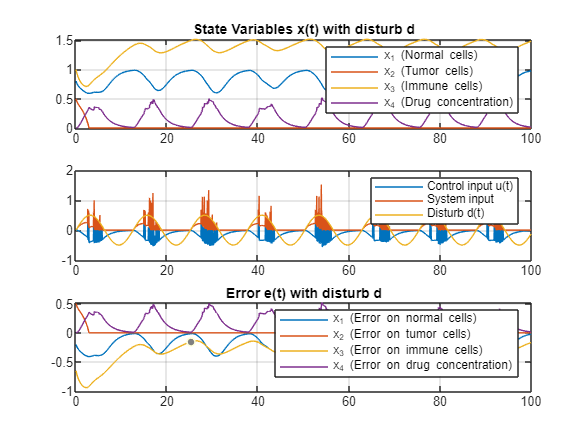

figure
subplot(3,1,1);
plot(t_mpc_d',X_hist(1:2401,:));
legend('x_1 (Normal cells)', 'x_2 (Tumor cells)', 'x_3 (Immune cells)', 'x_4 (Drug concentration)');
title('State Variables x(t) with disturb d');
grid on;
subplot(3,1,2);
plot(t_mpc_d',U_hist);
hold on;
plot(t_mpc_d',I_hist);
hold on;
plot(t_mpc_d',d_hist)
legend('Control input u(t)','System input','Disturb d(t)');
grid on;
subplot(3,1,3);
plot(t_mpc_d',error(1:2401,:));
title('Error e(t) with disturb d');
legend('x_1 (Error on normal cells)', 'x_2 (Error on tumor cells)', 'x_3 (Error on immune cells)', 'x_4 (Error on drug concentration)');
grid on;

## COMPARISON

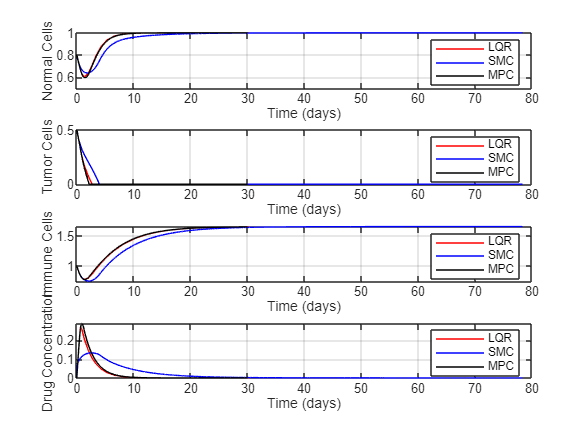

t_mpc = (0:Ts:Tsim); 
figure;
subplot(4,1,1) 
plot(LQR_normal_time(1:40), LQR_normal_data(1:40), 'r', 'DisplayName', 'LQR');
hold on;
plot(SMC_normal_time(1:5200), SMC_normal_data(1:5200), 'B', 'DisplayName', 'SMC');
plot(t_mpc',X_hist(1:721,1), 'k', 'DisplayName', 'MPC');
xlabel('Time (days)');
ylabel('Normal Cells');
grid on;
legend;
subplot(4,1,2) 
plot(LQR_tumor_time(1:40), LQR_tumor_data(1:40), 'r', 'DisplayName', 'LQR');
hold on;
plot(SMC_tumor_time(1:5200), SMC_tumor_data(1:5200), 'B', 'DisplayName', 'SMC');
plot(t_mpc',X_hist(1:721,2), 'k', 'DisplayName', 'MPC');
xlabel('Time (days)');
ylabel('Tumor Cells');
grid on;
legend;
subplot(4,1,3) 
plot(LQR_immune_time(1:40), LQR_immune_data(1:40), 'r', 'DisplayName', 'LQR');
hold on;
plot(SMC_immune_time(1:5200), SMC_immune_data(1:5200), 'B', 'DisplayName', 'SMC');
plot(t_mpc',X_hist(1:721,3), 'k', 'DisplayName', 'MPC');
xlabel('Time (days)');
ylabel('Immune Cells');
grid on;
legend;
subplot(4,1,4) 
plot(LQR_drug_time(1:40), LQR_drug_data(1:40), 'r', 'DisplayName', 'LQR');
hold on;
plot(SMC_drug_time(1:5200), SMC_drug_data(1:5200), 'B', 'DisplayName', 'SMC');
plot(t_mpc',X_hist(1:721,4), 'k', 'DisplayName', 'MPC');
xlabel('Time (days)');
ylabel('Drug Concentration');
grid on;
legend;

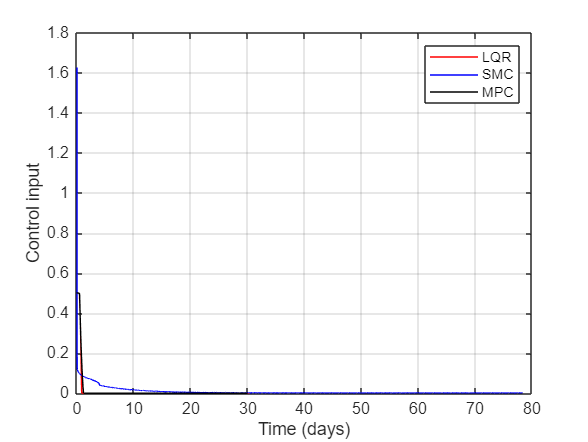


figure;
plot(LQR_control_time(1:40), LQR_control_data(1:40), 'r', 'DisplayName', 'LQR');
hold on;
plot(SMC_control_time(1:5200), SMC_control_data(1:5200), 'B', 'DisplayName', 'SMC');
plot(t_mpc',U_hist(1:721,1), 'k', 'DisplayName', 'MPC');
xlabel('Time (days)');
ylabel('Control input');
grid on;
legend;